# PHY 329 Homework 4

## Ryan Schlimme (eid: rjs4499)

# Problem 18.1

Given the data, perform a fit with 

x = [1, 2, 2.5, 3, 4, 5];
fx = [1, 5, 7, 8, 2, 1];

## Part a) Cubic Spline with Natural End Conditions

fxn = [0, 1, 5, 7, 8, 2, 1, 0];

p1 = spline(x, fxn)

p1 = struct with fields:
      form: 'pp'
    breaks: [1 2 2.5000 3 4 5]
     coefs: [5×4 double]
    pieces: 5
     order: 4
       dim: 1


## Part b) Cubic Spline with Not-a-Knot End Conditions

p2 = spline(x, fx)

p2 = struct with fields:
      form: 'pp'
    breaks: [1 2 2.5000 3 4 5]
     coefs: [5×4 double]
    pieces: 5
     order: 4
       dim: 1


## Part c) Piecewise Cubic Hermite Interpolation

p3 = pchip(x, fx)

p3 = struct with fields:
      form: 'pp'
    breaks: [1 2 2.5000 3 4 5]
     coefs: [5×4 double]
    pieces: 5
     order: 4
       dim: 1


# Problem 18.7

## Part a) Cubic spline with not-a-knot end conditions, plot

x = [1,3,5,6,7,9];
fx = [1.000, 2.172, 4.220, 5.430, 4.912, 9.120];

f = @(x) 0.0185*x.^5-0.444*x.^4 + 3.9125*x.^3 - 15.456*x.^2+27.069*x-14.1;

xx = linspace(0,10);

p = spline(x, fx, xx)

p =     0.2734    0.3593    0.4418    0.5213    0.5978    0.6716    0.7428    0.8117    0.8784    0.9432    1.0062    1.0677    1.1277    1.1866    1.2444    1.3015    1.3579    1.4140    1.4698    1.5256    1.5815    1.6379    1.6947    1.7523    1.8109    1.8706    1.9316    1.9941    2.0583    2.1245    2.1927    2.2632    2.3363    2.4120    2.4905    2.5722    2.6571    2.7454    2.8374    2.9332    3.0331    3.1372    3.2457    3.3589    3.4768    3.5997    3.7279    3.8614    4.0005    4.1453


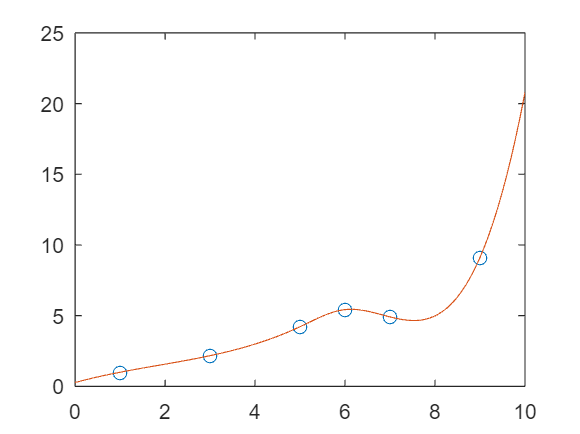


figure; plot(x, fx, "o", xx,p)

## Part b) Repeat Using Clamped End Conditions

df = @(x) 5*0.0185*x.^4-4*0.444*x.^3 + 3*3.9125*x.^2 - 2*15.456*x+27.069;

xu = df(9)

xu = 11.7870

xl = df(1)

xl = 6.2110


xnew = [6.2110, 1.000, 2.172, 4.220, 5.430, 4.912, 9.120, 11.7870];

xx = linspace(0,10);

p1 = spline(x, xnew, xx);

figure(1); plot(x, fx, "o",xx,p1)

# Problem 19.5

x = [0, 0.1, 0.3, 0.5, 0.7, 0.95, 1.2];
fx = [1, 0.9048, 0.7408, 0.6065, 0.4966, 0.3867, 0.3012];

## Part b) Trapezoidal Rule and Error

trapz(x, fx)

ans = 0.7012

## Part c) Trapezoidal and Simpson's Rule

# Problem 19.8

## Part a) Integration

t = [1, 2, 3.25, 4.5, 6, 7, 8, 8.5, 9, 10];
v = [5, 6, 5.5, 7, 8.5, 8, 6, 7, 7, 5];

z = trapz(t, v)

z = 60.1250

z / (10-1)

ans = 6.6806

## Part b) Cubic Fit

polyfit(t, v, 3)

ans =    -0.0180    0.1753    0.0603    4.8507


v(t) = -0.0180t^3 +0.1753t^2+0.0603t+4.8507

# Problem 19.13

x = [0, 4, 6, 8, 12, 16, 20];
rho = [4.00, 3.95, 3.89, 3.80, 3.60, 3.41, 3.30];
A = [100, 103, 106, 110, 120, 133, 150];

integrand = rho.*x

integrand =          0   15.8000   23.3400   30.4000   43.2000   54.5600   66.0000



m = trapz(x, integrand)

m = 708.3200

# Problem 19.10

## Part a) Composite Trapezoidal

f = @(z) 200 * (z / (5+z))*exp(-2*z/30);
d = z*f / f;

trap(f, 0, 30, 6)

ans = 1.4027e+03

trap(z*f, 0, 30, 6) / 

# Define Our Functions

% Golden Section Minimum

function I = trap(func, a, b, n, varargin)
if nargin<3, error("at least 3 args required"), end
if ~(b>a), error("upper bound must be greater than lower"), end
if nargin<4 || isempty(n), n = 100; end
x = a; h = (b-a)/n;
s = func(a, varargin{:});
for i = 1: n-1
    x = x+h;
    s = s+2*func(x, varargin{:});
end
s = s + func(b, varargin{:});
I = (b-a)*s/(2*n);
end